### Comparing our measurements of dorsal tongue fluorescence to other published data

We compare our fluorescence measurements of tongue and, in some cases, lower lip to fluorescence measurements of fluorescence published for same locations

A big effect is the peak fluorescence at 635 nm. This corresponds to the peak emission of Protoporphyrin IX (PpIX) present in P. gingivalis, a bacteria commonly found in the oral cavity. It is undisputed that Protoporphyrin IX (PpIX) has peak at 635 nm.

Interesting conjecture: The presence on the tongue is not surprising, but not necessarily good. It can spread to teeth, causing caries and to the gums causing gingivitus. It has aslo been reported to be a risk factor, including cardiovascular disease, rheumatoid arthritis, and even Alzheimer's disease (see paper cited 1888 times is Dominy, S. S., Lynch, C., Ermini, F., Benedyk, M., Marczyk, A., Konradi, A., ... & Potempa, J. (2019). Porphyromonas gingivalis in Alzheimer’s disease brains: Evidence for disease causation and treatment with small-molecule inhibitors. *Science advances*, *5*(1)), although there has been pushback from skeptics about causality. Also, Protoporphyrin IX (PpIX) is present in yogurt (can measure peak at 633 nn)

Interesting fact: The strongest absorption peak for Protoporphyrin IX (PpIX) is 405 (called the Soret band), but it also has weaker absorption peaks (called Q-bands) including 635 where it emits when illuminated with 405 nm light.  (see photodynamic therapy)

Interesting fact that that chlorophyll evolved from porphyrins and they also have Q-bands that overlap with emitted light - so plants   uv light, emit at longer wavelength(675 nm) , but then also reabsorb emitted light .  That helps in photosynthesis.  

%{
cd /Users/joyce/Github/isetcam; addpath(genpath(pwd));
cd /users/joyce/Github/oraleye/; addpath(genpath(pwd));
cd /users/joyce/Github/isetfluorescence/; addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/; addpath(genpath(pwd));
%}

wave = 500:700;

I think we should simplify the plots so that we only show the Veld et al data which is for one individual who they say is "representative". The other data were averaged across many subjects. 

Also, we can point out that the peak of protoporphyrin IX (PpIX) fluorescence is 630-633 which is the fluoroph0re in oral bacteria (aka Porphyromonas gingivalis or *P. gingivalis) *

Note also that peak excitation for this porphyrin is ~405 nm, so we expect porphyrin fluorescence to be highest at 405 than 415 and 450

### Tongue (deVeld)

de Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, D. J., Star, W. M., & Roodenburg, J. L. (2003).  Autofluorescence characteristics of healthy oral mucosa at different anatomical sites. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 32(5), 367-376

Figure 4, "Mean autofluorescence spectra of healthy oral mucosa obtained at four representative locations, excitation wavelength 405 nm" , cheek mucosa and the dorsal side of the tongue

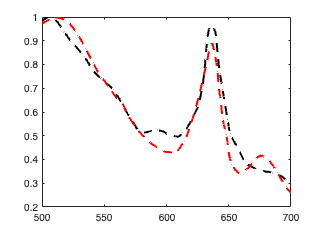

tongue = ieReadSpectra('TongueVeld2003.mat',wave);
ieNewGraphWin;

%plot(wave,tongue/max(tongue(:)),'k--','lineWidth',2); hold on;
plot(wave,tongue/tongue(1),'k--','lineWidth',2); hold on;

### Tongue (Mallia)

Mallia, R. J., Thomas, S. S., Mathews, A., Kumar R, R., Sebastian, P., Madhavan, J., & Subhash, N. (2008). Laser‐induced autofluorescence spectral ratio reference standard for early discrimination of oral cancer. *Cancer*, *112*(7), 1503-1512.

Fig 3 " LIAF emission spectra from oral mucosa were recorded in the 420–720 nm spectral range on a miniature fiberoptic spectrometer from 14 anatomical sites of 35 healthy volunteers and 91 sites of 44 patients, with **excitation at 404 nm** from a diode laser."

This may be averaged across subjects

% tongue = ieReadSpectra('DorsalTongueMallia2008.mat',wave);
% %plot(wave,tongue/max(tongue(:)),'r--','lineWidth',2); hold on;
% plot(wave,tongue/tongue(1),'r--','lineWidth',2); hold on;

## Read a couple of raw data sets

This is the database of raw measurements.

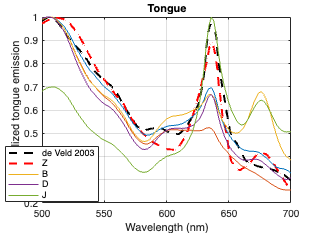

[T,dataDir] = oeDatabaseCreate;

files405Z = ieTableGet(T,'subject','Z','substrate','tongue','e wave',405,'e level',980,'return','files');
files405B = ieTableGet(T,'subject','B','substrate','tongue','e wave',405,'e level',980,'return','files');
files405D = ieTableGet(T,'subject','D','substrate','tongue','e wave',405,'e level',980,'return','files');
files405J = ieTableGet(T,'subject','J','substrate','tongue','e wave',405,'e level',980,'return','files');
tongueFiles = cat(1,files405Z,files405B,files405D,files405J);

tongueData = zeros(numel(wave),numel(tongueFiles));

for ii=1:numel(tongueFiles)
    data = ieReadSpectra(fullfile(dataDir,tongueFiles{ii}),wave); 
    tongueData (:,ii) = data(:);
    %plot(wave,data/max(data(:))); hold on;
    plot(wave,data/data(1)); hold on;
end
legend({'de Veld 2003', 'Z1','Z2', 'B','D','J'});

title('Tongue');
xlabel('Wavelength (nm)'); ylabel('Normalized tongue emission'); grid on;